ns = [10 20 40 80 100]

ns =     10    20    40    80   100


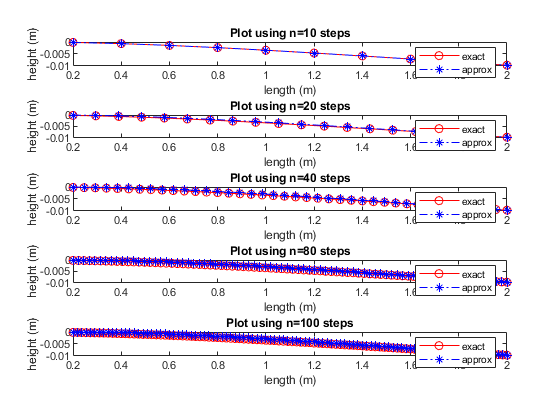


for i = 1:numel(ns)
    x = linspace(0.2, 2, ns(i))';
    y1 = yexact(ns(i));
    y2 = beamCompact(ns(i));
    subplot(5, 1, i)
    plot(x, y1,'r-o', x, y2, 'b-.*')
    legend('exact', 'approx')
    title(sprintf('Plot using n=%d steps', ns(i)))
    xlabel('length (m)')
    ylabel('height (m)')
end